%% ============================================================
% Scenario-2: Monsoon Season CNN-BiLSTM MME
% Monsoon months: June to October (1970-2014)
%% ============================================================

clc; clear; close all;


excelFile = 'GCM data.xlsx';

gridLon = 82.625;
gridLat = 21.875;

%% ================= SCENARIO-2 SETTINGS =======================

% Monsoon season: June to October
monsoonMonths = 6:10;

% 75% training and 25% testing
trainRatio = 0.75;

%% ================= SCENARIO-2 CNN-BiLSTM HYPERPARAMETERS =====
kernelSize       = 2;
dropoutRate      = 0.20;
maxEpochs        = 120;
miniBatchSize    = 64;
initialLearnRate = 0.005;

% BiLSTM hidden units
numHiddenUnits = 12;

rng(42);

%% ================= LOAD EXCEL DATA ===========================

T = readtable(excelFile, 'VariableNamingRule', 'preserve');

disp('Excel columns detected:');

Excel columns detected:


disp(T.Properties.VariableNames');

    {'Date'         }
    {'IMD'          }
    {'ACCESS-CM2'   }
    {'ACCESS-ESM1-5'}
    {'BCC-CSM2-MR'  }
    {'CanESM5'      }
    {'EC-Earth3'    }
    {'EC-Earth3-Veg'}
    {'INM-CM4-8'    }
    {'INM-CM5-0'    }
    {'MPI-ESM1-2-HR'}
    {'MPI-ESM1-2-LR'}
    {'MRI-ESM2-0'   }
    {'NorESM2-LM'   }
    {'NorESM2-MM'   }




%% ================= READ DATE COLUMN ==========================

dateCol = 'Date';

if ~ismember(dateCol, T.Properties.VariableNames)
    error('Date column not found. Please check the Excel header.');
end

datesRaw = T.(dateCol);

if isdatetime(datesRaw)
    dates = datesRaw;
elseif isnumeric(datesRaw)
    dates = datetime(datesRaw, 'ConvertFrom', 'excel');
else
    dates = datetime(datesRaw, 'InputFormat', 'M/d/yyyy');
end

%% ================= EXTRACT IMD AND SELECTED GCM DATA =========

imdCol = 'IMD';

if ~ismember(imdCol, T.Properties.VariableNames)
    error('IMD column not found. Please check the Excel header.');
end

Y = T.(imdCol);

% Selected five GCMs for MME
gcmCols = { ...
    'EC-Earth3'
    'EC-Earth3-Veg'
    'MPI-ESM1-2-HR'
    'MPI-ESM1-2-LR'
    'INM-CM4-8'};

missingCols = setdiff(gcmCols, T.Properties.VariableNames);

if ~isempty(missingCols)
    disp('Missing GCM columns:');
    disp(missingCols');
    error('Some selected GCM columns are missing in the Excel file.');
end

fprintf('\nSelected GCMs used for Scenario-2 CNN-BiLSTM MME:\n');


Selected GCMs used for Scenario-2 CNN-BiLSTM MME:


disp(gcmCols');

    {'EC-Earth3'}    {'EC-Earth3-Veg'}    {'MPI-ESM1-2-HR'}    {'MPI-ESM1-2-LR'}    {'INM-CM4-8'}




X = T{:, gcmCols};

X = double(X);
Y = double(Y);

numGCM = size(X,2);

fprintf('Number of selected GCMs used = %d\n', numGCM);

Number of selected GCMs used = 5



%% ================= REMOVE MISSING VALUES =====================

validIdx = ~isnat(dates) & all(~isnan(X),2) & ~isnan(Y);

dates = dates(validIdx);
X = X(validIdx,:);
Y = Y(validIdx);

fprintf('\nTotal valid daily records before monsoon filtering = %d\n', length(Y));


Total valid daily records before monsoon filtering = 16436



%% ================= FILTER MONSOON SEASON ONLY ================

idxMonsoon = ismember(month(dates), monsoonMonths);

datesMonsoon = dates(idxMonsoon);
XMonsoon = X(idxMonsoon,:);
YMonsoon = Y(idxMonsoon);

fprintf('Total monsoon daily records = %d\n', length(YMonsoon));

Total monsoon daily records = 6885



%% ================= CREATE TEMPORAL SEQUENCES =================
% Look-back window for temporal learning
lookBack = 7;

% Each sample uses previous lookBack monsoon records.
% Input sequence size: [number of GCMs x lookBack]
% Output: IMD rainfall at current monsoon day.

XSeq = cell(length(YMonsoon)-lookBack+1, 1);
YSeq = nan(length(YMonsoon)-lookBack+1, 1);
dateSeq = NaT(length(YMonsoon)-lookBack+1, 1);

count = 0;

for i = lookBack:length(YMonsoon)

    count = count + 1;

    Xi = XMonsoon(i-lookBack+1:i, :)';   % [numGCM x lookBack]
    Yi = YMonsoon(i);                    % current-day IMD rainfall

    XSeq{count,1} = Xi;
    YSeq(count,1) = Yi;
    dateSeq(count,1) = datesMonsoon(i);

end

fprintf('Total monsoon sequence samples after look-back = %d\n', numel(YSeq));

Total monsoon sequence samples after look-back = 6879



%% ================= 75% TRAINING AND 25% TESTING ==============

numSamples = numel(YSeq);
numTrain = floor(trainRatio * numSamples);

idxTrain = 1:numTrain;
idxTest  = numTrain+1:numSamples;

XTrain = XSeq(idxTrain);
YTrain = YSeq(idxTrain);

XTest = XSeq(idxTest);
YTest = YSeq(idxTest);

dateTrain = dateSeq(idxTrain);
dateTest  = dateSeq(idxTest);

fprintf('\nScenario-2 chronological split applied:\n');


Scenario-2 chronological split applied:


fprintf('Training samples = %d\n', numel(YTrain));

Training samples = 5159


fprintf('Testing samples  = %d\n', numel(YTest));

Testing samples  = 1720



%% ================= NORMALIZATION =============================

% Compute normalization parameters from training data only
XTrainAll = cat(2, XTrain{:});   % [numGCM x total_sequence_steps]

muX = mean(XTrainAll, 2, 'omitnan');
sigX = std(XTrainAll, 0, 2, 'omitnan');
sigX(sigX == 0) = 1;

muY = mean(YTrain, 'omitnan');
sigY = std(YTrain, 0, 'omitnan');

if sigY == 0
    sigY = 1;
end

% Normalize input sequences
for i = 1:numel(XTrain)
    XTrain{i} = (XTrain{i} - muX) ./ sigX;
end

for i = 1:numel(XTest)
    XTest{i} = (XTest{i} - muX) ./ sigX;
end

% Normalize target
YTrainN = (YTrain - muY) ./ sigY;

%% ================= CNN-BiLSTM ARCHITECTURE ===================

% Scenario-2 settings:
% Kernel size = 2
% Dropout = 0.20
% Three learnable blocks are used:
% Conv layer 1 + Conv layer 2 + BiLSTM

layers = [
    sequenceInputLayer(numGCM, "Name", "input")

    convolution1dLayer(kernelSize, 16, ...
        "Padding", "same", ...
        "Name", "conv1")
    reluLayer("Name", "relu1")

    convolution1dLayer(kernelSize, 32, ...
        "Padding", "same", ...
        "Name", "conv2")
    reluLayer("Name", "relu2")

    bilstmLayer(numHiddenUnits, ...
        "OutputMode", "last", ...
        "Name", "bilstm")

    dropoutLayer(dropoutRate, "Name", "dropout")

    fullyConnectedLayer(1, "Name", "fc_out")
    regressionLayer("Name", "regression")
];

%% ================= TRAINING OPTIONS ==========================

options = trainingOptions("adam", ...
    "MaxEpochs", maxEpochs, ...
    "MiniBatchSize", miniBatchSize, ...
    "InitialLearnRate", initialLearnRate, ...
    "Shuffle", "every-epoch", ...
    "Verbose", true, ...
    "Plots", "training-progress");

%% ================= TRAIN MODEL ===============================

fprintf('\nTraining Scenario-2 CNN-BiLSTM model for monsoon season...\n');


Training Scenario-2 CNN-BiLSTM model for monsoon season...


Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         1.01 |          0.5 |          0.0050 |
|       1 |          50 |       00:00:01 |         0.86 |          0.4 |          0.0050 |
|       2 |         100 |       00:00:01 |         0.80 |          0.3 |          0.0050 |
|       2 |         150 |       00:00:01 |         0.99 |          0.5 |          0.0050 |
|       3 |         200 |       00:00:02 |         1.16 |          0.7 |          0.0050 |
|       4 |         250 |       00:00:02 |         0.64 |          0.2 |          0.0050 |
|       4 |         300 |       00:00:02 |         0.77 |         

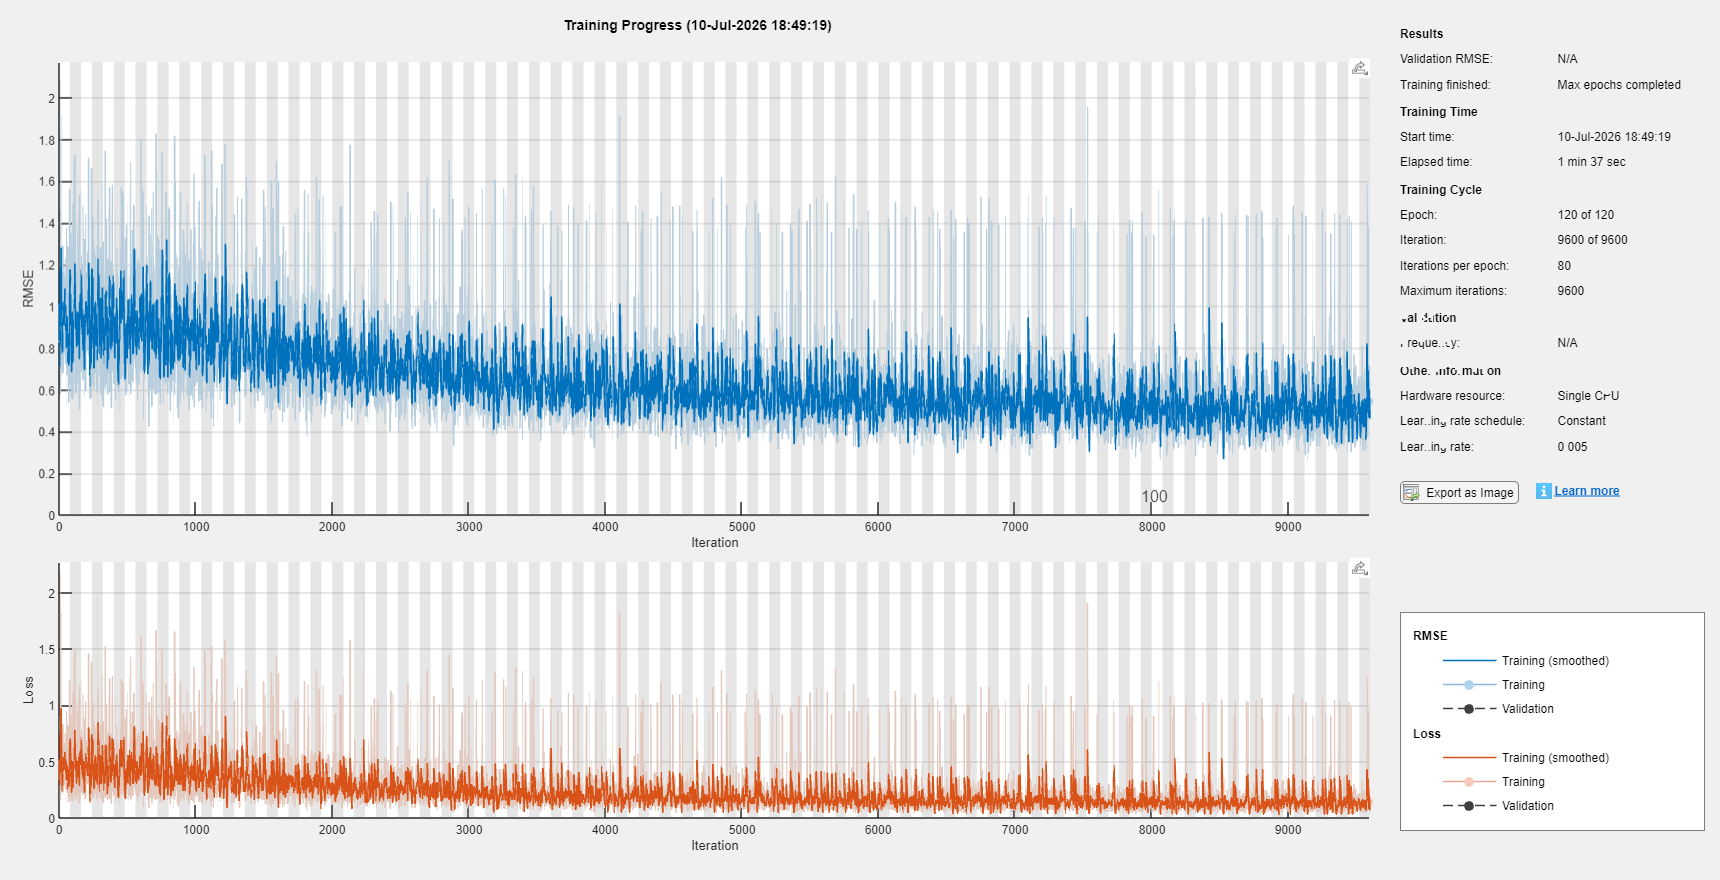


tic
net = trainNetwork(XTrain, YTrainN, layers, options);

trainingTime = toc;

fprintf('Training completed in %.2f seconds.\n', trainingTime);

Training completed in 99.08 seconds.



%% ================= PREDICTION ================================

YPredTrainN = predict(net, XTrain, "MiniBatchSize", miniBatchSize);
YPredTestN  = predict(net, XTest,  "MiniBatchSize", miniBatchSize);

% Denormalize predictions
YPredTrain = YPredTrainN .* sigY + muY;
YPredTest  = YPredTestN  .* sigY + muY;

% Rainfall cannot be negative
YPredTrain(YPredTrain < 0) = 0;
YPredTest(YPredTest < 0)   = 0;


%% ================= PERFORMANCE METRICS =======================

trainMetrics = computeMetrics(YTrain, YPredTrain);
testMetrics  = computeMetrics(YTest, YPredTest);

fprintf('\n================ SCENARIO-2 TRAINING PERFORMANCE ================\n');


================ SCENARIO-2 TRAINING PERFORMANCE ================


fprintf('Correlation (r) = %.3f\n', trainMetrics.r);

Correlation (r) = 0.861


fprintf('RMSE            = %.3f mm/day\n', trainMetrics.RMSE);

RMSE            = 6.787 mm/day


fprintf('PBias           = %.3f %%\n', trainMetrics.PBias);

PBias           = -3.245 %


fprintf('KGE             = %.3f\n', trainMetrics.KGE);

KGE             = 0.796



fprintf('\n================ SCENARIO-2 TESTING PERFORMANCE =================\n');


================ SCENARIO-2 TESTING PERFORMANCE =================


fprintf('Correlation (r) = %.3f\n', testMetrics.r);

Correlation (r) = 0.862


fprintf('RMSE            = %.3f mm/day\n', testMetrics.RMSE);

RMSE            = 7.068 mm/day


fprintf('PBias           = %.3f %%\n', testMetrics.PBias);

PBias           = -9.682 %


fprintf('KGE             = %.3f\n', testMetrics.KGE);

KGE             = 0.790


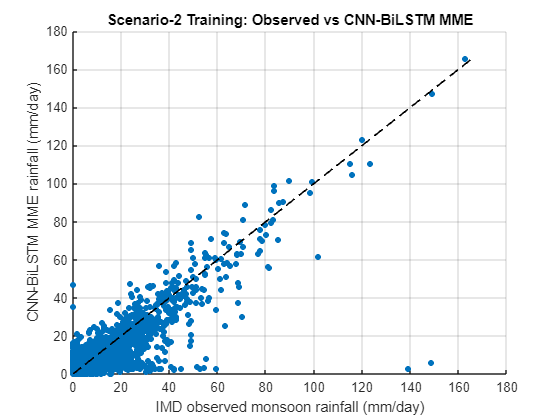


%% ================= PLOTS =====================================

% Training scatter plot
figure;
scatter(YTrain, YPredTrain, 20, 'filled'); hold on;
maxVal = max([YTrain; YPredTrain], [], 'omitnan');
plot([0 maxVal], [0 maxVal], 'k--', 'LineWidth', 1.2);
grid on;
xlabel('IMD observed monsoon rainfall (mm/day)');
ylabel('CNN-BiLSTM MME rainfall (mm/day)');
title('Scenario-2 Training: Observed vs CNN-BiLSTM MME');

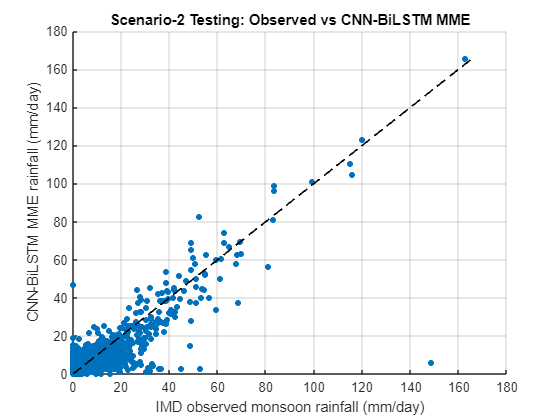


% Testing scatter plot
figure;
scatter(YTest, YPredTest, 20, 'filled'); hold on;
maxVal = max([YTest; YPredTest], [], 'omitnan');
plot([0 maxVal], [0 maxVal], 'k--', 'LineWidth', 1.2);
grid on;
xlabel('IMD observed monsoon rainfall (mm/day)');
ylabel('CNN-BiLSTM MME rainfall (mm/day)');
title('Scenario-2 Testing: Observed vs CNN-BiLSTM MME');


%% ================= LOCAL FUNCTION ============================


function metrics = computeMetrics(obs, sim)

    obs = obs(:);
    sim = sim(:);

    valid = ~isnan(obs) & ~isnan(sim);
    obs = obs(valid);
    sim = sim(valid);

    metrics.r = corr(obs, sim, 'Rows', 'complete');

    metrics.RMSE = sqrt(mean((sim - obs).^2, 'omitnan'));

    % PBias formulation:
    % Negative PBias = overestimation
    % Positive PBias = underestimation
    metrics.PBias = 100 * sum(obs - sim, 'omitnan') / sum(obs, 'omitnan');

    if numel(obs) < 3 || std(obs) == 0 || mean(obs) == 0
        metrics.KGE = NaN;
    else
        r = metrics.r;
        alpha = std(sim) / std(obs);
        beta  = mean(sim) / mean(obs);

        metrics.KGE = 1 - sqrt((r - 1)^2 + ...
                                (alpha - 1)^2 + ...
                                (beta - 1)^2);
    end

end